# Miniprojekt 2 - Fkrevensanalyse af målte vibrationssignaler

## Indledning

## 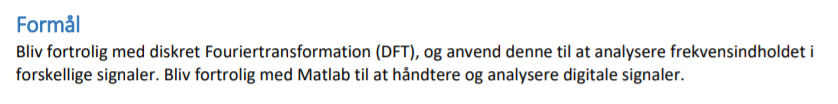

## Loading af fil

VI vil starte med at loade signalet ind i Matlab sammen med dens samplingfrekvens.

load("Opgave2_audiofil_1_1.mat");

Nu da vi har loaded signalet ind, kan vi starte med at plotte de første fem sekunder.

## Plot af signal

Først laves den korrekte skalering af amplituden, da 1 volt svarer til 100 enheder.

raw_input = raw_input.*0.01;

Først beregnes sample periode tiden med formlen:


$$\textrm{Ts}=\frac{1}{\textrm{Fs}}$$


Ts=1/fs

Ts = 3.9063e-05

Nu laves en tidsakse på fem sekunder:

t=0:Ts:5;

Et array over alle elemneter laves:

n=0:length(raw_input)-1;

Signalet kan nu plottes:

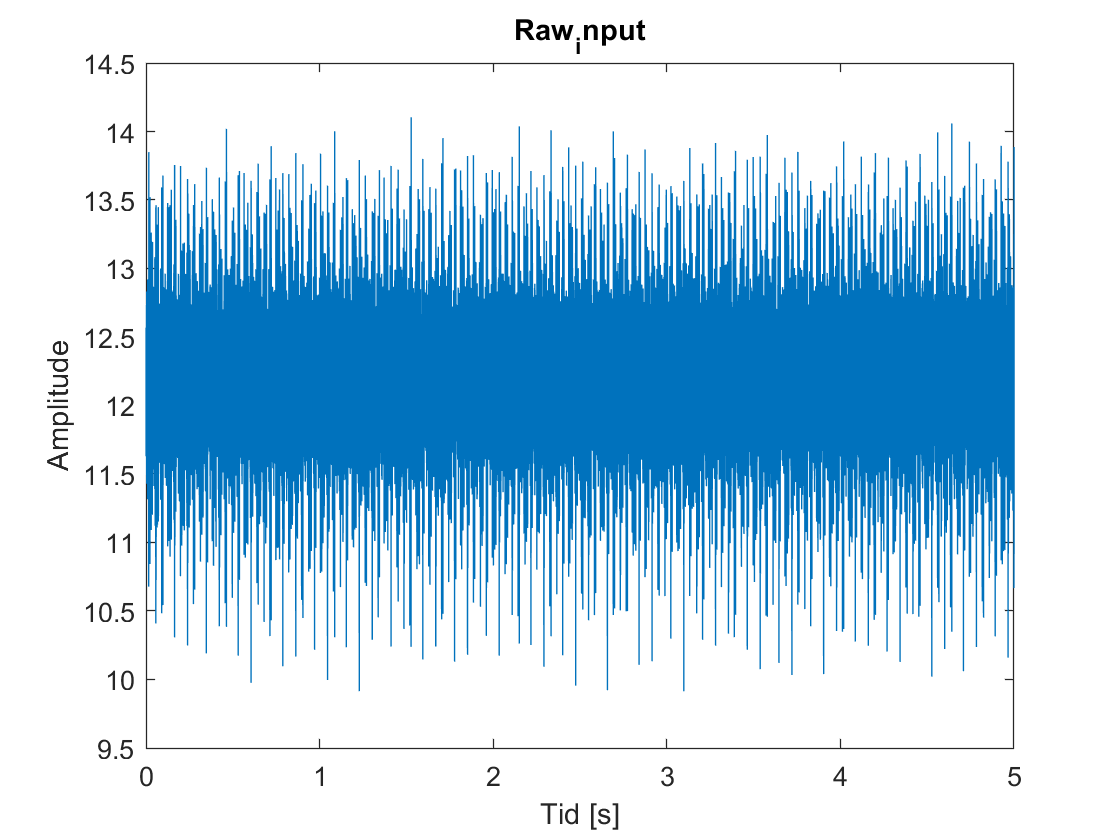

plot(n*Ts,raw_input)
title('Raw_input')
xlabel('Tid [s]')
ylabel('Amplitude')
xlim([0 5])
%ylim([(min(raw_input)*1.2) (max(raw_input)*0.8)])
hold off